# Datos Generales

mp = 120                % Masa persona kg

mp = 120

ms = 20                 % Masa silla kg

ms = 20

pp = mp * 9.81          % Peso persona N sugerencia

pp = 1.1772e+03

ps = ms * 9.81          % Peso silla N

ps = 196.2000

mt = mp + ms            % Masa total kg

mt = 140

pt = pp + ps            % Peso total N

pt = 1.3734e+03

# Datos Perfiles

lbc = 430               % Longitud barra corta mm

lbc = 430

lbl = 2360              % Longitud barra larga mm

lbl = 2360

lbm = 355               % longitud barra motor mm

lbm = 355

pbc = 3.08 / 1000       % Masa teórico calculado barra corta kg/mm

pbc = 0.0031

pbl = 6.39 / 1000       % Masa teórico calculado barra larga kg/mm 

pbl = 0.0064

#### ***Areas***

- ***Perfil 1 - 50 x 50 ***

b11 = 50            % mm

b11 = 50

h11 = 50            % mm

h11 = 50

A11 = b11 * h11     % mm^2

A11 = 2500


b12 = 46            % mm

b12 = 46

h12 = 46            % mm

h12 = 46

A12 = b12 * h12     % mm^2

A12 = 2116


A1 = A11 - A12      % mm^2

A1 = 384

- ***Perfil 2 - 70 x 70***

b21 = 70            % mm

b21 = 70

h21 = 70            % mm

h21 = 70

A21 = b21 * h21     % mm^2

A21 = 4900


b22 = 67            % mm

b22 = 67

h22 = 67            % mm

h22 = 67

A22 = b22 * h22     % mm^2

A22 = 4489


A2 = A21 - A22      % mm^2

A2 = 411

#### ***Momentos de Inercia***

- *** Perfil 1 - 50 x 50***

I1 = ((b11 * h11^3) / 12) - ((b12 * h12^3) / 12)    % mm^4

I1 = 147712

c1 = h11 / 2                                        % mm

c1 = 25

- *** Perfil 1 - 70 x 70***

I2 = ((b21 * h21^3) / 12) - ((b22 * h22^3) / 12)    % mm^4

I2 = 3.2157e+05

c2 = h21 / 2                                        % mm

c2 = 35

# Movimiento del Marco

alpha = 0      %Grados Balanceo

alpha = 0

betha = 0      %Grados Cabeceo

betha = 0

# Peso de las vigas

- ***Viga 430 mm - Perfil 1***

m1 = pbc*lbc*9.81       %N

m1 = 12.9924

- ***Viga 355 mm - Perfil 1***

m2 = pbc*lbm*9.81       %N

m2 = 10.7263

- ***Viga 2360 mm -Perfil 2***

m3 = pbl*lbl*9.81       %N

m3 = 147.9387

# Fuerzas

- ***Fuerza Total (Peso Viga + Fuerza Externa)***

W1 = pt/2 + m1        %Vigas 430mm (N)

W1 = 699.6924

W2 = m2             %Vigas 355mm (N)

W2 = 10.7263

W3 = m3             %Vigas 2360mm (N)

W3 = 147.9387

- ***Fuerza Fa***

Fa = 13528.2/2      %N

Fa = 6.7641e+03

- ***Fuerza Fm***

Fm = 6.4128e+03      %N

Fm = 6.4128e+03

## ***Componentes de las Fuerzas***

Cx = cosd(alpha).*sind(betha);
Cy = sind(alpha);
Cz = cosd(alpha).*cosd(betha);


- ***W1***

W1x = W1.*Cx

W1x = 0

W1y = W1.*Cy

W1y = 0

W1z = W1.*Cz

W1z = 699.6924

- ***W2***

W2x = W2.*Cx

W2x = 0

W2y = W2.*Cy

W2y = 0

W2z = W2.*Cz

W2z = 10.7263

- ***W3***

W3x = W3.*Cx

W3x = 0

W3y = W3.*Cy

W3y = 0

W3z = W3.*Cz

W3z = 147.9387

- ***Fa***

Fax = Fa.*Cx

Fax = 0

Fay = Fa.*Cy

Fay = 0

Faz = Fa.*Cz

Faz = 6.7641e+03

- ***Fm***

Fmx = -Fm.*Cx

Fmx = 0

Fmy = -Fm.*Cy

Fmy = 0

Fmz = -Fm.*Cz

Fmz = -6.4128e+03

# Análisis de Vigas

## 1. Viga 1

a = lbc/2;        %Distancia de aplicacion de la Carga
X1 = 0:0.05:lbc;

### Plano yz

[R1z,M1y,R2z,M2y,R1x,R2x] = Doble_Simple(W1z,a,lbc,-W1x)

R1z = 349.8462

M1y = 3.7608e+04

R2z = 349.8462

M2y = 3.7608e+04

R1x = 0

R2x = 0

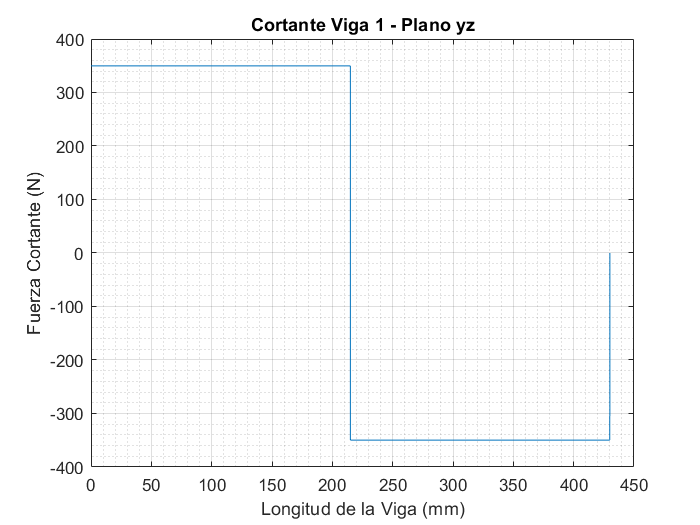


V1yz = R1z - W1z.*ctstep(X1-a)+R2z.*(X1==lbc);
plot(X1,V1yz)
grid on
grid minor
title('Cortante Viga 1 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V1max_yz = max(V1yz)            %(N)

V1max_yz = 349.8462

V1min_yz = min(V1yz)            %(N)

V1min_yz = -349.8462

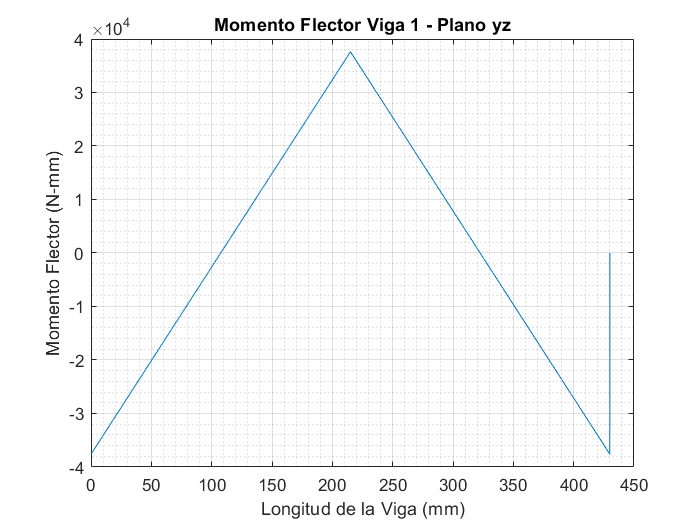


M1yz = -M1y + R1z.*(X1)-W1z.*ctstep(X1-a).*(X1-a)+M2y.*(X1==lbc);
plot(X1,M1yz)
grid on
grid minor
title('Momento Flector Viga 1 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M1max_yz = max(abs(M1yz))            %(N-mm)

M1max_yz = 3.7608e+04

### Plano xz

[R1y,M1z,R2y,M2z,R1x,R2x] = Doble_Simple(W1y,a,lbc,-W1x)

R1y = 0

M1z = 0

R2y = 0

M2z = 0

R1x = 0

R2x = 0

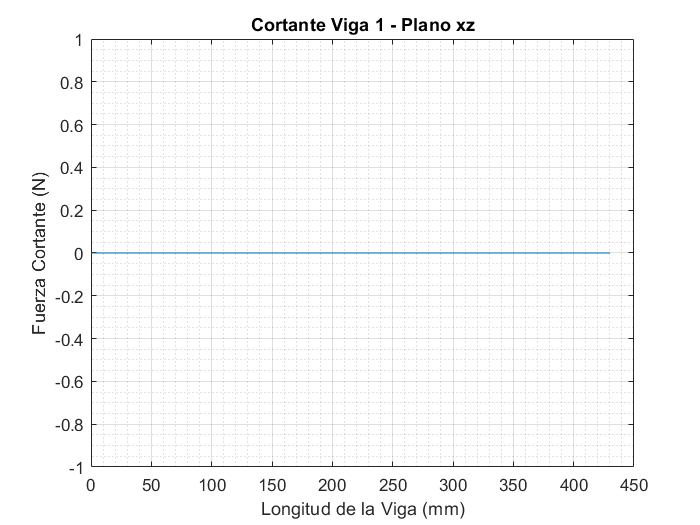


V1xz = R1y - W1y.*ctstep(X1-a)+R2y.*(X1==lbc);
plot(X1,V1xz)
grid on
grid minor
title('Cortante Viga 1 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V1max_xz = max(V1xz)            %(N)

V1max_xz = 0

V1min_xz = min(V1xz)            %(N)

V1min_xz = 0

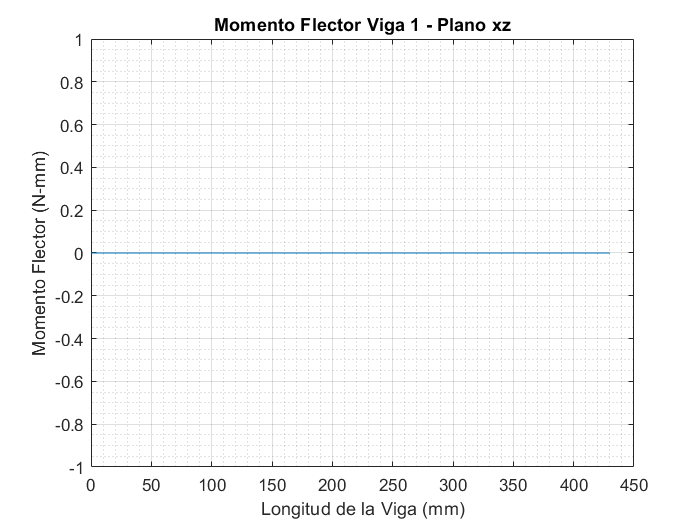


M1xz = -M1z + R1y.*(X1)-W1y.*ctstep(X1-a).*(X1-a)+M2z.*(X1==lbc);
plot(X1,M1xz)
grid on
grid minor
title('Momento Flector Viga 1 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M1max_xz = max(abs(M1xz))            %(N-mm)

M1max_xz = 0


Emax1 = (M1max_yz * c1) / I1

Emax1 = 6.3652

## 2. Viga 2

a = lbc/2;          %Distancia de aplicacion de la Carga
X1 = 0:0.05:lbc;

### Plano yz

[R3z,M3y,R4z,M4y,R3x,R4x] = Doble_Simple(W1z,a,lbc,-W1x)

R3z = 349.8462

M3y = 3.7608e+04

R4z = 349.8462

M4y = 3.7608e+04

R3x = 0

R4x = 0

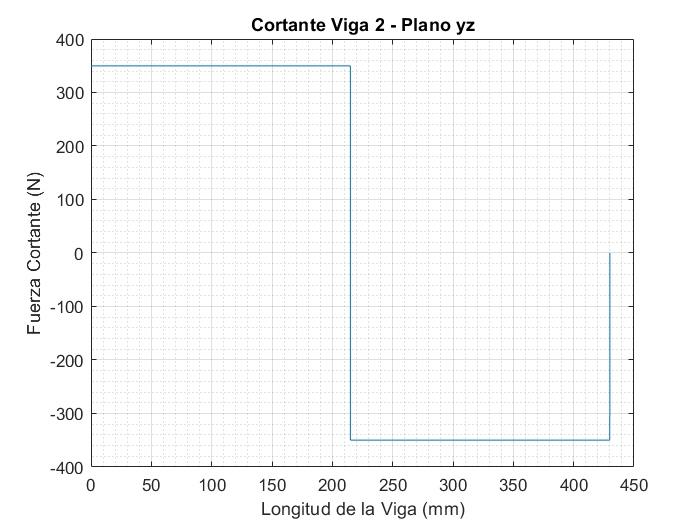


V2yz = R3z - W1z.*ctstep(X1-a)+R4z.*(X1==lbc);
plot(X1,V2yz)
grid on
grid minor
title('Cortante Viga 2 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V2max_yz = max(V2yz)            %(N)

V2max_yz = 349.8462

V2min_yz = min(V2yz)            %(N)

V2min_yz = -349.8462

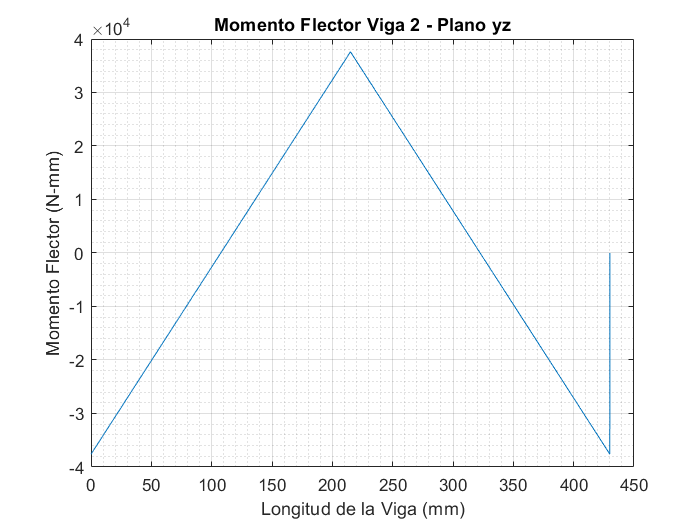


M2yz = -M3y + R3z.*(X1)-W1z.*ctstep(X1-a).*(X1-a)+M4y.*(X1==lbc);
plot(X1,M2yz)
grid on
grid minor
title('Momento Flector Viga 2 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M2max_yz = max(abs(M2yz))            %(N-mm)

M2max_yz = 3.7608e+04

### Plano xz

[R3y,M3z,R4y,M4z,R3x,R4x] = Doble_Simple(W1y,a,lbc,-W1x)

R3y = 0

M3z = 0

R4y = 0

M4z = 0

R3x = 0

R4x = 0

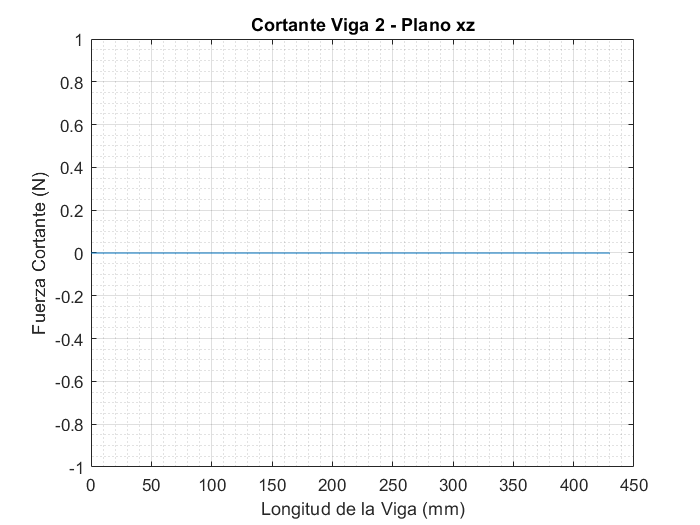


V2xz = R3y - W1y.*ctstep(X1-a)+R4y.*(X1==lbc);
plot(X1,V2xz)
grid on
grid minor
title('Cortante Viga 2 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V2max_xz = max(V2xz)            %(N)

V2max_xz = 0

V2min_xz = min(V2xz)            %(N)

V2min_xz = 0

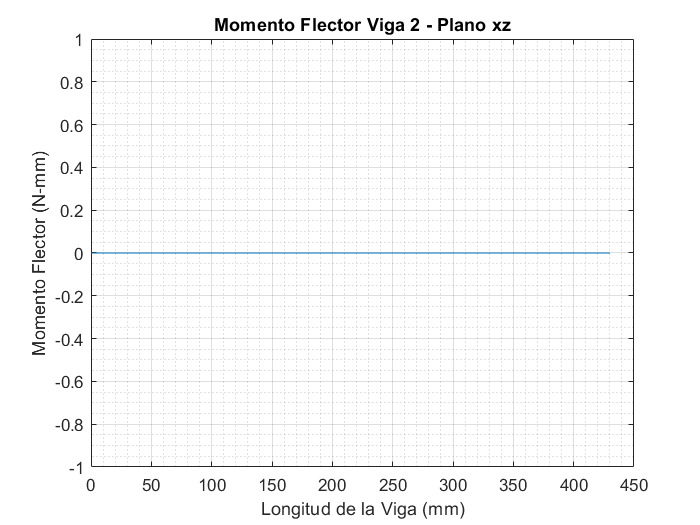


M2xz = -M3z + R3y.*(X1)-W1y.*ctstep(X1-a).*(X1-a)+M4z.*(X1==lbc);
plot(X1,M2xz)
grid on
grid minor
title('Momento Flector Viga 2 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M2max_xz = max(M2xz)            %(N-mm)

M2max_xz = 0

M2min_xz = min(M2xz)            %(N-mm)

M2min_xz = 0

Emax2 = (abs(M2max_yz) * c1) / I1;

## 3. Viga 4

a = lbm/3;           %Distancia de aplicacion de la Carga 1
b = lbm/2;           %Distancia de aplicación de la Carga 2
b1 = b-a;
c = lbm-b;

X1 = 0:0.001:lbm;

### Plano yz

[R9z,M9y,R10z,M10y,R9x,R10x] = Doble_Doble(Fmz,W2z,a,b1,c,Fmx,W2x) 

R9z = -6.1629e+03

M9y = 8.8205e+05

R10z = -239.1862

M10y = 2.1002e+05

R9x = 0

R10x = 0

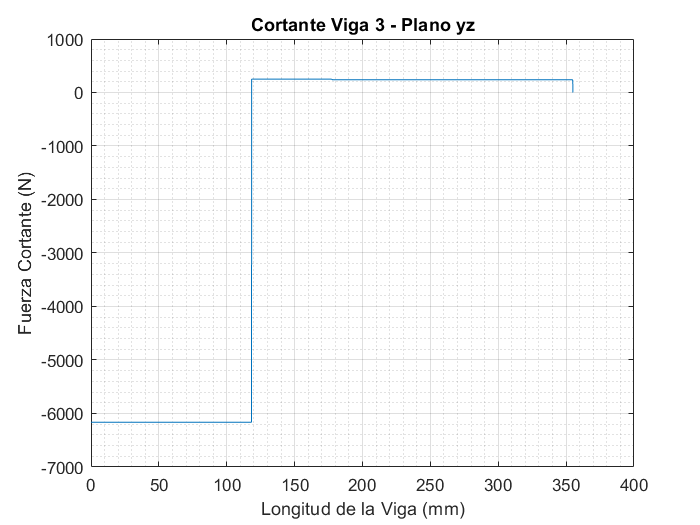


V3yz = R9z-Fmz.*ctstep(X1-a)-W2z.*ctstep(X1-b)+R10z.*(X1==lbm);
plot(X1,V3yz)
grid on
grid minor
title('Cortante Viga 3 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V3max_yz = max(V3yz)            %(N)

V3max_yz = 249.9125

V3min_yz = min(V3yz)            %(N)

V3min_yz = -6.1629e+03

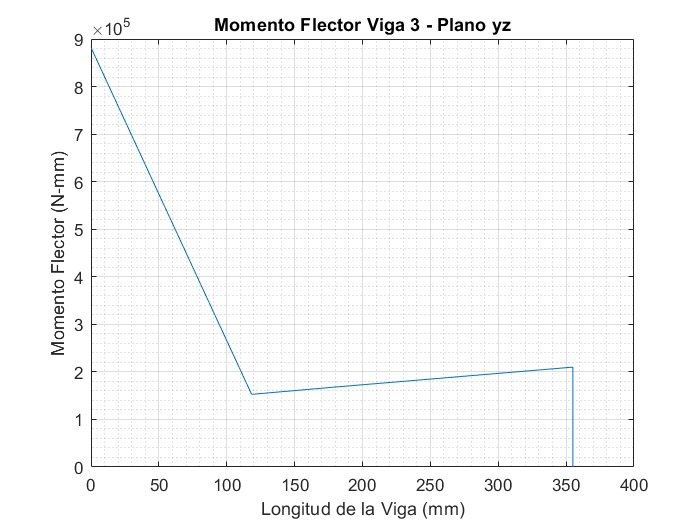


M3yz = M9y+R9z.*X1-Fmz.*ctstep(X1-a).*(X1-a)-W2z.*ctstep(X1-b).*(X1-b)-M10y.*(X1==lbm);
plot(X1,M3yz)
grid on
grid minor
title('Momento Flector Viga 3 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M3max_yz = max(abs(M3yz))            %(N-mm)

M3max_yz = 8.8205e+05

### Plano xz

[R9y,M9z,R10y,M10z,R9x,R10x] = Doble_Doble(Fmy,W2y,a,b1,c,Fmx,W2x) 

R9y = 0

M9z = 0

R10y = 0

M10z = 0

R9x = 0

R10x = 0

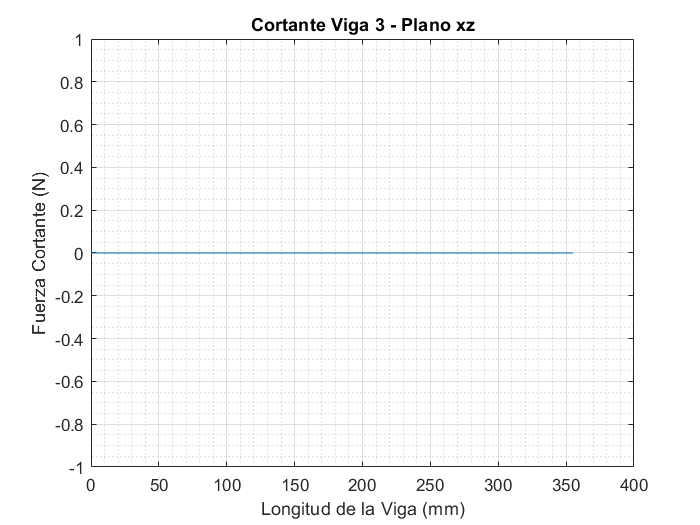


V3xz = R9y-Fmy.*ctstep(X1-a)-W2y.*ctstep(X1-b)+R10y.*(X1==lbm);

plot(X1,V3xz)
grid on
grid minor
title('Cortante Viga 3 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V3max_xz = max(V3xz)            %(N)

V3max_xz = 0

V3min_xz = min(V3xz)            %(N)

V3min_xz = 0

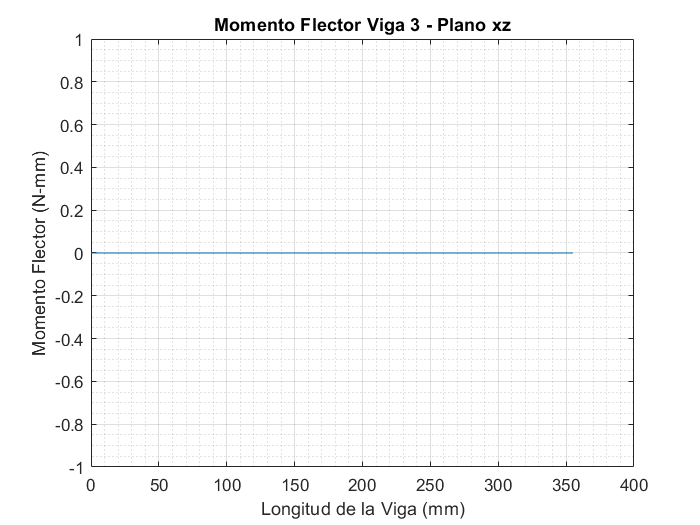


M3xz = M9z+R9y.*X1-Fmy.*ctstep(X1-a).*(X1-a)-W2y.*ctstep(X1-b).*(X1-b)-M10z.*(X1==lbm);
plot(X1,M3xz)
grid on
grid minor
title('Momento Flector Viga 3 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M3max_xz = max(M3xz)            %(N-mm)

M3max_xz = 0

M3min_xz = min(M3xz)            %(N-mm)

M3min_xz = 0

Emax4 = (abs(M3max_yz) * c1) / I1;

## 4. Viga 3

a = 90;           %Distancia de aplicacion de la Carga 1
b = lbc/2;           %Distancia de aplicación de la Carga 2
b1 = b-a;
c = lbc-b;

X1 = 0:0.001:lbc;

### Plano yz

[R5z,M5y,R6z,M6y,R5x,R6x] = Doble_Doble(-abs(R9z),W1z,a,b1,c,-abs(R9y),W1x) 

R5z = -5.6222e+03

M5y = 5.8528e+05

R6z = 159.0316

M6y = 1.1267e+05

R5x = 0

R6x = 0

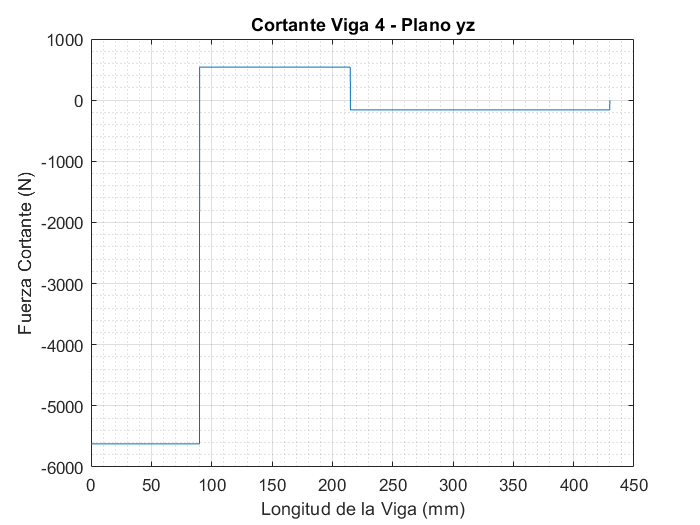


V4yz = R5z-R9z.*ctstep(X1-a)-W1z.*ctstep(X1-b)+R6z.*(X1==lbc);
plot(X1,V4yz)
grid on
grid minor
title('Cortante Viga 4 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V4max_yz = max(V4yz)            %(N)

V4max_yz = 540.6607

V4min_yz = min(V4yz)            %(N)

V4min_yz = -5.6222e+03

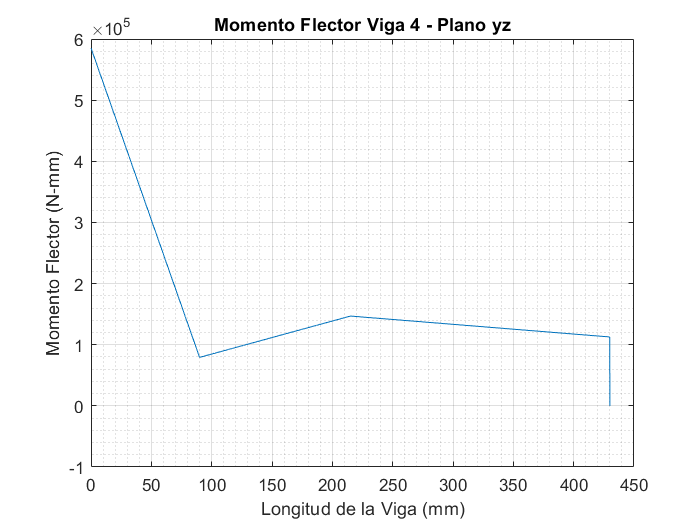


M4yz = M5y+R5z.*X1-R9z.*ctstep(X1-a).*(X1-a)-W1z.*ctstep(X1-b).*(X1-b)-M6y.*(X1==lbc);
plot(X1,M4yz)
grid on
grid minor
title('Momento Flector Viga 4 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M4max_yz = max(abs(M4yz))            %(N-mm)

M4max_yz = 5.8528e+05

### Plano xz

[R5y,M5z,R6y,M6z,R5x,R6x] = Doble_Doble(abs(R9x),W1y,a,b1,c,-abs(R9y),W1x) 

R5y = 0

M5z = 0

R6y = 0

M6z = 0

R5x = 0

R6x = 0

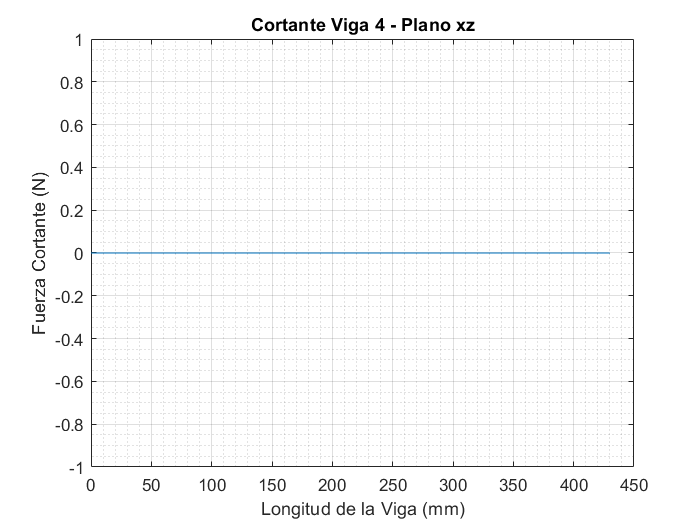


V4xz = R5y+R9x.*ctstep(X1-a)-W1y.*ctstep(X1-b)+R6y.*(X1==lbc);

plot(X1,V4xz)
grid on
grid minor
title('Cortante Viga 4 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V4max_xz = max(V4xz)            %(N)

V4max_xz = 0

V4min_xz = min(V4xz)            %(N)

V4min_xz = 0

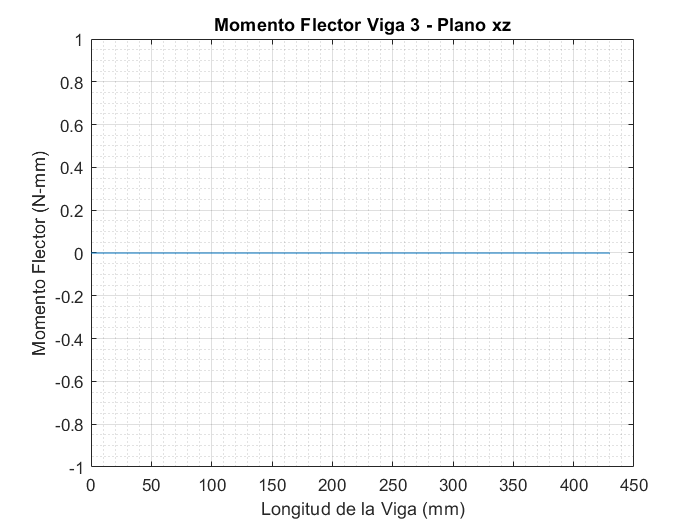


M4xz = M5z+R5y.*X1+R9x.*ctstep(X1-a).*(X1-a)-W1y.*ctstep(X1-b).*(X1-b)-M6z.*(X1==lbc);
plot(X1,M4xz)
grid on
grid minor
title('Momento Flector Viga 3 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M4max_xz = max(M4xz)            %(N-mm)

M4max_xz = 0

M4min_xz = min(M4xz)            %(N-mm)

M4min_xz = 0

Emax3 = (abs(M4max_yz) * c1) / I1;

### Torque

[M5x,M6x] = Torque(-abs(M9y),a,b1+c)

M5x = -6.9744e+05

M6x = -1.8462e+05

M9y = -M9y

M9y = -8.8205e+05

## 5. Viga 5

a = 90;           %Distancia de aplicacion de la Carga 1
b1 = lbc/2;          %Distancia de aplicación de la Carga 2
b = b1-a;
c = lbc/2;           %Distancia de aplicación de la carga 3
L = lbc;

X1 = 0:0.001:lbc;

### Plano yz

[R7z,M7y,R8z,M8y,R7x,R8x] = Doble_Triple(-abs(R10z),W1z,Faz,a,b,c,L,-abs(R10y),W1x,Fax)

R7z = -5.3262e+03

M7y = -5.7739e+05

R8z = -977.3475

M8y = 3.2773e+05

R7x = 0

R8x = 0

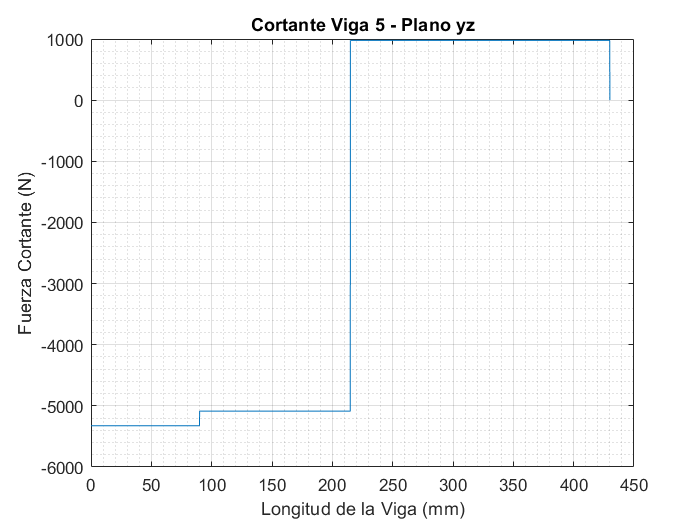


V5yz = R7z+abs(R10z).*ctstep(X1-a)-W1z.*ctstep(X1-b1)+Faz.*ctstep(X1-c)+R8z.*(X1==lbc);
plot(X1,V5yz)
grid on
grid minor
title('Cortante Viga 5 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V5max_yz = max(V5yz)            %(N)

V5max_yz = 977.3475

V5min_yz = min(V5yz)            %(N)

V5min_yz = -5.3262e+03

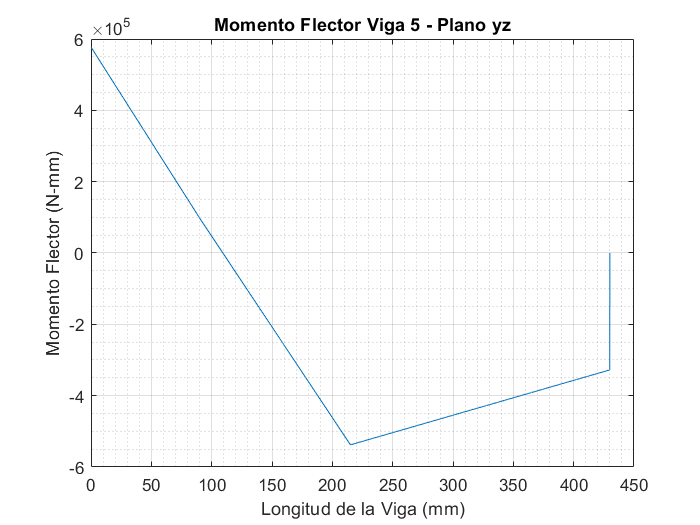


M5yz = -M7y+R7z.*X1+abs(R10z).*ctstep(X1-a).*(X1-a)-W1z.*ctstep(X1-b1).*(X1-b1)+Faz.*ctstep(X1-c).*(X1-c)+M8y.*(X1==lbc);
plot(X1,M5yz)
grid on
grid minor
title('Momento Flector Viga 5 - Plano yz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M5max_yz = max(abs(M5yz))            %(N-mm)

M5max_yz = 5.7739e+05

### Plano xz

[R7y,M7z,R8y,M8z,R7x,R8x] = Doble_Triple(abs(R10x),W1y,Fay,a,b,c,L,-abs(R10y),W1x,Fax) 

R7y = -6.2997e-09

M7z = -2.7057e-06

R8y = 6.2997e-09

M8z = 3.1499e-09

R7x = 0

R8x = 0

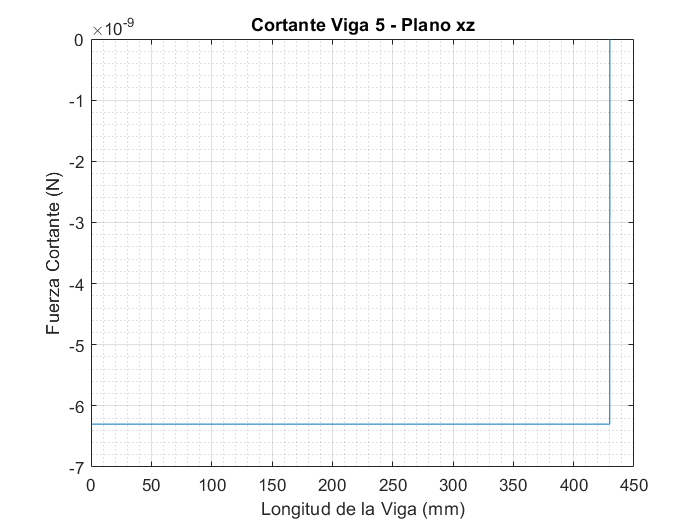


V5xz = R7y-abs(R10x).*ctstep(X1-a)-W1y.*ctstep(X1-b1)+Fay.*ctstep(X1-c)+R8y.*(X1==lbc);

plot(X1,V5xz)
grid on
grid minor
title('Cortante Viga 5 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V5max_xz = max(V5xz)            %(N)

V5max_xz = 0

V5min_xz = min(V5xz)            %(N)

V5min_xz = -6.2997e-09

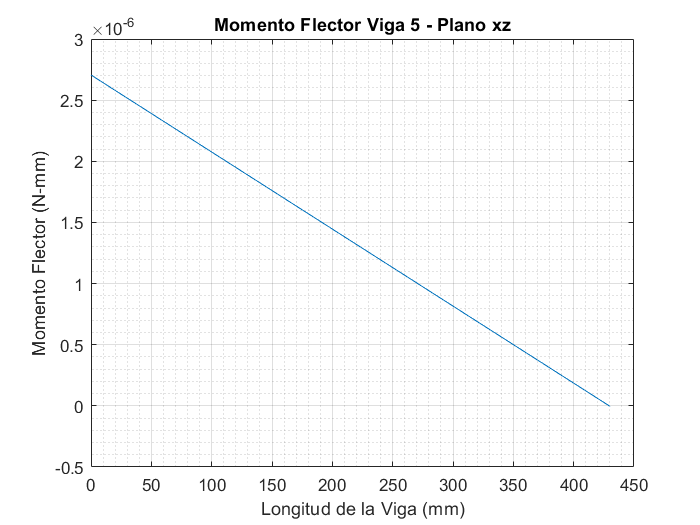


M5xz = -M7z+R7y.*X1-abs(R10x).*ctstep(X1-a).*(X1-a)-W1y.*ctstep(X1-b1).*(X1-b1)+Fay.*ctstep(X1-c).*(X1-c)+M8z.*(X1==lbc);
plot(X1,M5xz)
grid on
grid minor
title('Momento Flector Viga 5 - Plano xz')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M5max_xz = max(M5xz)            %(N-mm)

M5max_xz = 2.7057e-06

M5min_xz = min(M5xz)            %(N-mm)

M5min_xz = -3.1436e-09


Emax5 = (abs(M5max_yz) * c1) / I1;

### Torque

[M7x,M8x] = Torque(abs(M10y),a,L-a)

M7x = 1.6606e+05

M8x = 4.3957e+04

M10y = -M10y

M10y = -2.1002e+05

## 6. Viga 6

L = lbl/2;                     % mm
a = 355;      %Distancia entre la viga 1 y 2  (mm)
b = 180;      %Distancia entre la viga 2 y 3  (mm)
c = 355;      %Distancia entre la viga 3 y 4  (mm)
d = 585/2;      %Distancia entre la viga 4 y el centro de la viga (mm)
X1 = 0:0.005:L;

### Plano YZ

R11z = -R1z-R3z-R5z-R7z-(W3z/2)

R11z = 1.0175e+04

M11x = M5x+M7x+(R1z).*L+(R3z).*(L-a)+(R5z).*(c+d)+(R7z).*(d)+(W3z/2).*(L/2)

M11x = -4.9846e+06

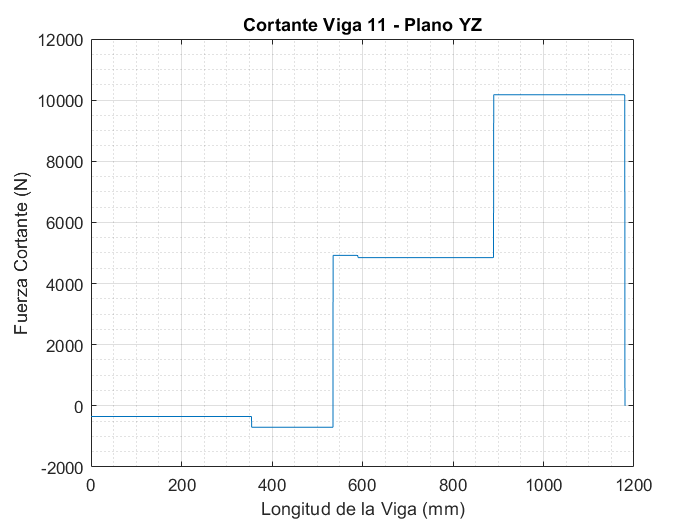


V11yz = -R1z-R3z.*ctstep(X1-a)-R5z.*ctstep(X1-(a+b))-R7z.*ctstep(X1-(a+b+c))-(W3z/2).*ctstep(X1-L/2)-R11z.*(X1==L);

plot(X1,V11yz)
grid on
grid minor
title('Cortante Viga 11 - Plano YZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V11max_yz = max(V11yz)            %(N)

V11max_yz = 1.0175e+04

V11min_yz = min(V11yz)            %(N)

V11min_yz = -699.6924

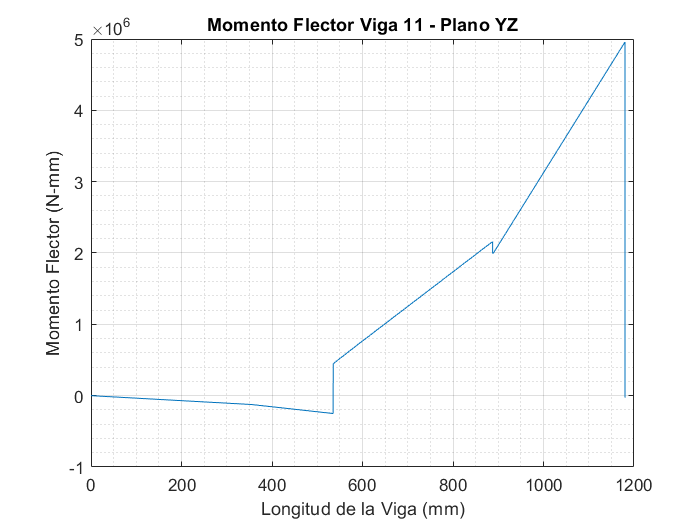


M11yz = -M5x.*ctstep(X1-(a+b))-M7x.*ctstep(X1-(L-d))-R1z.*X1-R3z.*ctstep(X1-a).*(X1-a)-R5z.*ctstep(X1-(a+b)).*(X1-(a+b))-R7z.*ctstep(X1-(a+b+c)).*(X1-(a+b+c))-(W3z/2).*ctstep(X1-L/2).*(X1-L/2)+M11x.*(X1==L);
plot(X1,M11yz)
grid on
grid minor
title('Momento Flector Viga 11 - Plano YZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M11max_yz = max(abs(M11yz))            %(N-mm)

M11max_yz = 4.9572e+06

M11min_yz = min(M11yz)            %(N-mm)

M11min_yz = -2.5014e+05

### Plano YX

R11x = -R1x-R3x-R5x-R7x-(W3x/2)

R11x = 0

M11z = M5z+M7z+(R1x).*L+(R3x).*(L-a)+(R5x).*(c+d)+(R7x).*(d)+(W3x/2).*(L/2)

M11z = -2.7057e-06

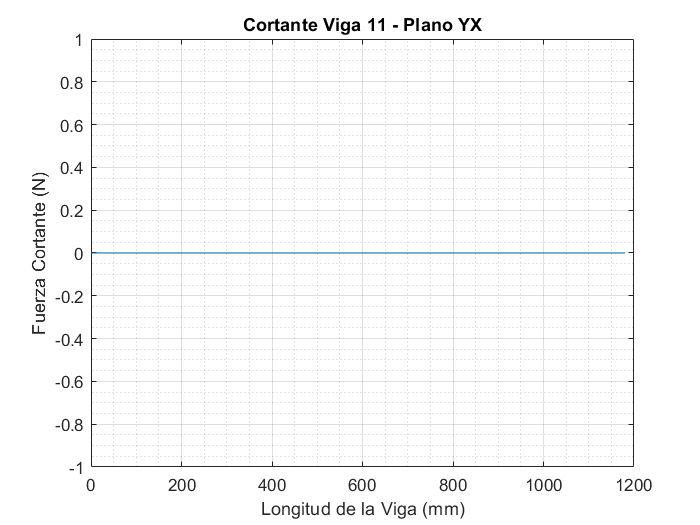


V11yx = R1x+R3x.*ctstep(X1-a)+R5x.*ctstep(X1-(a+b))+R7x.*ctstep(X1-(a+b+c))+(W3x/2).*ctstep(X1-L/2)+R11x.*(X1==L);

plot(X1,V11yx)
grid on
grid minor
title('Cortante Viga 11 - Plano YX')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V11max_yx = max(V11yx)            %(N)

V11max_yx = 0

V11min_yx = min(V11yx)            %(N)

V11min_yx = 0

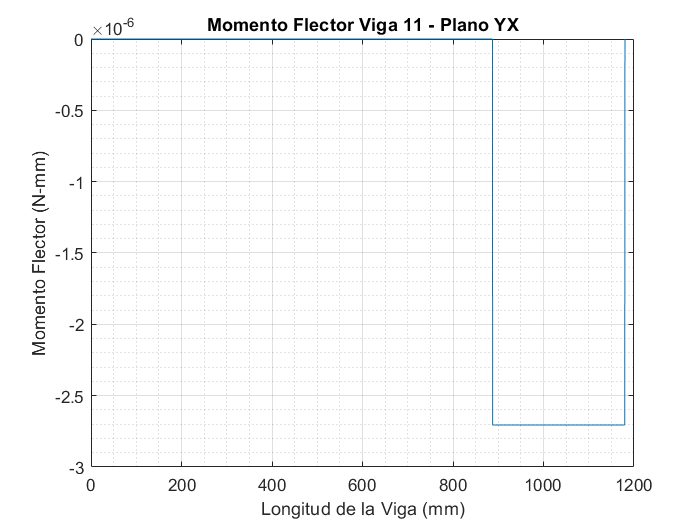


M11yx = M5z.*ctstep(X1-(a+b))+M7z.*ctstep(X1-(L-d))+R1x.*X1+R3x.*ctstep(X1-a).*(X1-a)+R5x.*ctstep(X1-(a+b)).*(X1-(a+b))+R7x.*ctstep(X1-(a+b+c)).*(X1-(a+b+c))+(W3x/2).*ctstep(X1-L/2).*(X1-L/2)-M11z.*(X1==L);
plot(X1,M11yx)
grid on
grid minor
title('Momento Flector Viga 11 - Plano YX')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M11max_yx = max(M11yx)            %(N-mm)

M11max_yx = 0

M11min_yx = min(M11yx)            %(N-mm)

M11min_yx = -2.7057e-06


Emax6=(M11max_yz*c2/I2)

Emax6 = 539.5399

### Torque

M11y = M1y +M3y + M5y + M7y

M11y = 8.3113e+04

# Viga Doblemente Empotrada: Carga Puntual

function[Ay,Ma,By,Mb,Ax,Bx] = Doble_Simple(P,a,L,F)
b = L-a;
Ay =((P*(b^2))/(L^3)).*(b+(3.*a));
Ma =(P*(b^2)*a)/(L^2);
By =((P*(a^2))/(L^3)).*(a+(3.*b));
Mb =(P*(a^2)*b)/(L^2);

Ax =(F*b)/(a+b);
Bx =(F*a)/(a+b);
end

# Viga Doblemente Empotrada: Doble Carga Puntual

function[Ay,Ma,By,Mb,Ax,Bx] = Doble_Doble(P,N,a,b,c,F,T)
d = a+b;
L = a+b+c;

By = -((3*P*(a^2))-(6*P*a*b)-(6*P*a*c)-(4*P*(a^3))+(3*N*(d^2))-(6*N*c*(d^2))-(4*N*(d^3)))/((L^2)*((4*L)-3));
Mb = ((4*P*(a^3))-(8*L*P*(a^2))+(3*P*(a^2))+(6*P*a*b)+(6*P*a*c)+(4*N*(d^3))-(4*L*N*(d^2))+(6*N*c*(d^2)))/((2*L)*((4*L)-3));
Ay = P+N-By;
Ma = Mb-(P*a)-(N*d)+(By*L);

Bx = (T*(b+a)+(F*a))/(a+b+c);
Ax = F+T-Bx;
end

# Viga Doblemente Empotrada: Triple Carga Puntual

function[Ay,Ma,By,Mb,Ax,Bx] = Doble_Triple(P,N,F,a,b,c,L,K,T,H)
d = a+b;
By = ((3*P*(a^3))-(3*P*L*(a^2))+(2*N*(d^3))-(3*N*L*(d^2))-(2+F*(c^3))+(3*F*L*(c^2)))/((3*(L^2))-(4*(L^3)));
%Mb = (-(P*(a^3))-(2*P*(a^2)*(L^2))+(3*P*L*(a^2))-(2*N*(L^2)*(d^2))-(N*(d^3))+(F*(c^3))+(2*F*(L^2)*(c^2))-(3*F*L*(c^2)))/((L^2)*((4*L)-3));
Mb = (1/(2*L)).*(-(P*(a^2))-(N*(d^2))+(F*(c^2))+(By*L));
Ay = P+N-F-By;
Ma = Mb+(P*a)-(F*c)+(N*d)-(By*L);

Bx = ((a*(K+T+H))+(b*(T+H))+(H*(abs((L-(a+b))-(L-c)))))/L;
Ax = K+T+H-Bx;
end

# Torque

function [M1,M2] = Torque(T,a,b)
M2 = T/((b/a)+1);
M1 = (T*b)/(a+b);
end

# Escalón Unitario

function [u] = ctstep(t)
u = (t>=0).*(1) + (t<0).*(0);
end